# [Solutions] DMFT+NRG

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the DMFT+NRG function

The complete version of the function is uploaded as `NRG/DMFT_Hubbard.m`. Compare with your implementation!

## Solution to Exercise (b): Obtain the DMFT+NRG solutions starting from the $U = 0$ result

*Note:* the computing time for Exercises (b) and (c) is quite huge and many log messages are generated during the computation. I suppress them in this solution.

The numerical result for this Exercise can be obtained by the following steps. First, we treat the $U=0$ case to obtain the initial hybridization function.

clear

% system parameters
U = 0;
mu = 0; 
T = 1e-4;
D = 1;

% initial hybridization function
ozin = [-1;1];
RhoV2in = [1;1]/2*(D/2)^2;

% NRG parameters
Lambda = 4;
N = 30;
Nkeep = 300;

% run DMFT+NRG
[ocont,RhoV2s,iscvg] = DMFT_Hubbard (U,mu,T,D,ozin,RhoV2in,Lambda,N,Nkeep);

RhoV2init_met = RhoV2s(:,end); % initial hyb. func.

Now we treat finite $U$'s.

Us = (2:0.3:3.5);
mus = Us/2; % half filling

RhoV2_met = cell(1,numel(Us));

for itU = (1:numel(Us))
    [~,RhoV2_met{itU}] = DMFT_Hubbard(Us(itU),mus(itU),T,D, ...
        ocont,RhoV2init_met,Lambda,N,Nkeep);
end

How do the results look like?

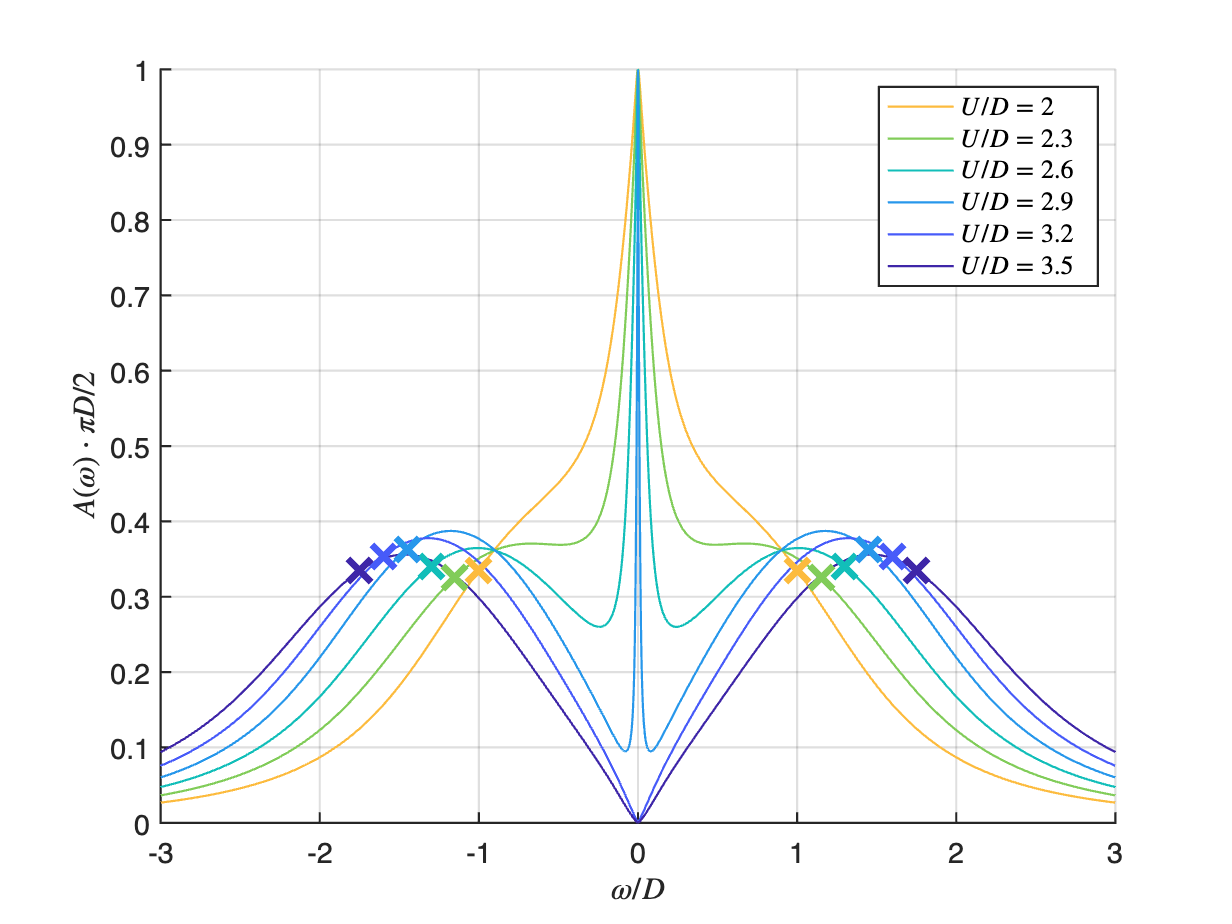

cmap = parula(round(numel(Us)*1.2));
cmap = flipud(cmap(1:numel(Us),:)); % to avoid too bright colors
legs = cell(1,numel(Us));

figure;
hold on;
for itU = (1:numel(Us))
    plot(ocont/D,RhoV2_met{itU}(:,end)/((D/2)^2)*(pi*D/2), ...
        'LineWidth',1,'Color',cmap(itU,:));
    legs{itU} = ['$U/D = ',sprintf('%.4g',Us(itU)/D),'$'];
end
% guide to the eye; mark \omega = \pm U/2
for itU = (1:numel(Us))
    plot([-1;1]*(Us(itU)/2/D),interp1(ocont/D, ...
        RhoV2_met{itU}(:,end)/((D/2)^2)*(pi*D/2), ...
        [-1;1]*(Us(itU)/2/D),'linear'),'x', ...
        'LineWidth',3,'MarkerSize',15,'Color',cmap(itU,:));
end
hold off;

grid on;
set(gca,'LineWidth',1,'FontSize',13);
legend(legs,'Interpreter','latex');
xlabel('$\omega / D$','Interpreter','latex');
ylabel('$A(\omega) \cdot \pi D/2$','Interpreter','latex');
xlim([-1 1]*(3*D));

For $U/D \leq 2.9$, the spectral function $A(\omega)$ has a peak centered at $\omega = 0$, and the peak gets narrowed as $U$ increases. This peak is called the quasiparticle peak, and its presence means that the system is metallic. (Hence `_met` in the variable names `RhoV2init_met` and `RhoV2_met`.) The height of the quasiparticle peak at $T = 0$ is pinned to $2/\pi D$, independent of $U$. Indeed, the height is dictated by the Luttinger theorem, which relates the height with the filling and the non-interacting density of states.

Moreover, for $U/D \leq 2.9$ there are two side peaks centered around $\omega = \pm U/2$. These side peaks are called the Hubbard bands. For $U/D \leq 2.3$, the Hubbard bands look like mere shoulders, but for larger $U$ they are better separated from the quasiparticle peak.

For $U/D \geq 3.2$, the quasiparticle peak disappears and only the Hubbard bands remain. There is a gap at $\omega = 0$, which is the Mott gap. So the system is insulating.

We see that for $U/D \leq 2.9$ the DMFT loop takes more iterations as $U$ increases.

disp(Us/D);

    2.0000    2.3000    2.6000    2.9000    3.2000    3.5000



disp(cellfun(@(x) size(x,2), RhoV2_met));

     5     7    10    23    21    14



Why? Let's plot how the curves change as the iteration proceeds for $U/D = 2.9$.

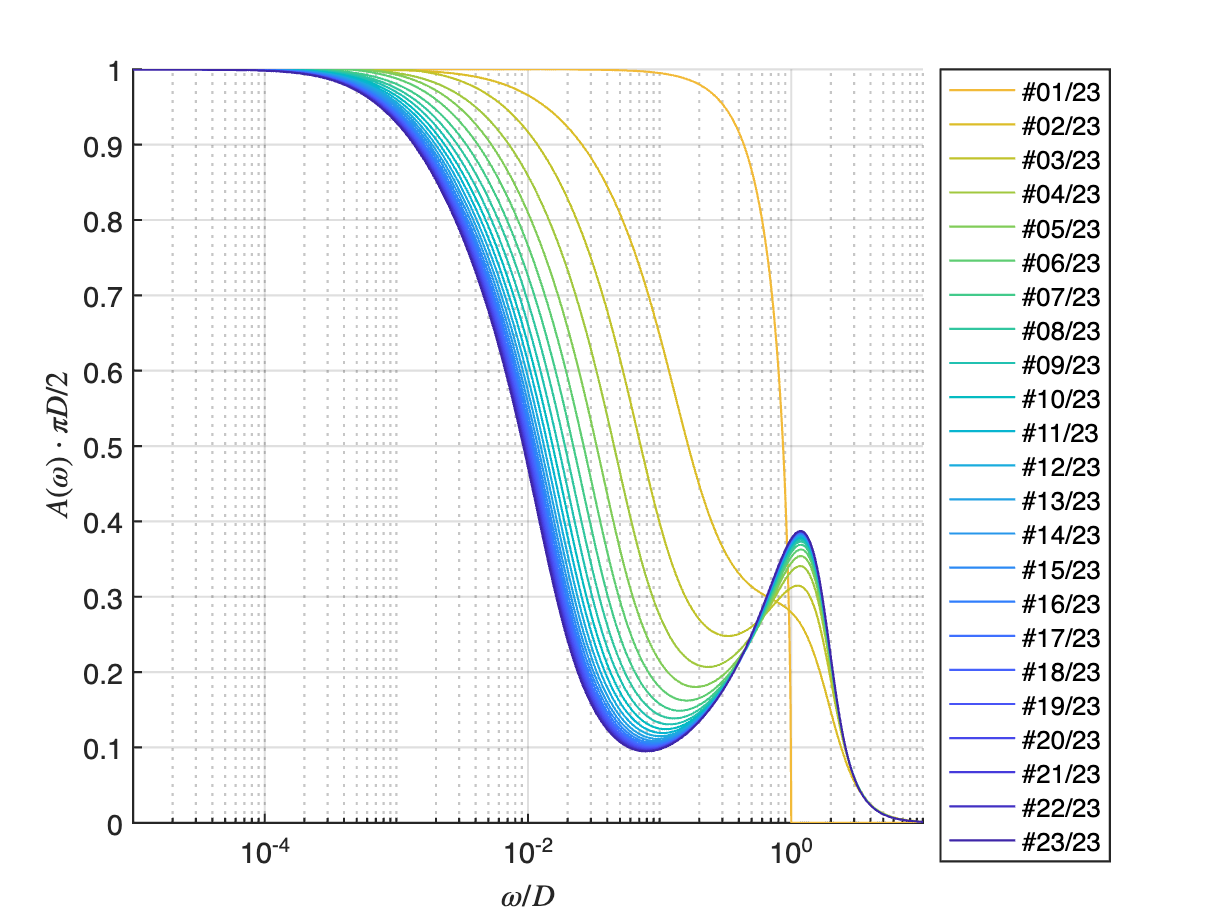

itU = 4;
cmap = parula(round(size(RhoV2_met{itU},2)*1.2));
cmap = flipud(cmap(1:size(RhoV2_met{itU},2),:)); % to avoid too bright colors
legs = cell(1,size(RhoV2_met{itU},2));

figure;
hold on;
for itd = (1:size(RhoV2_met{itU},2))
    plot(ocont/D,RhoV2_met{itU}(:,itd)/((D/2)^2)*(pi*D/2), ...
        'LineWidth',1,'Color',cmap(itd,:));
    legs{itd} = sprintf('#%02i/%02i',[itd size(RhoV2_met{itU},2)]);
end
hold off;

grid on;
set(gca,'LineWidth',1,'FontSize',13,'XScale','log');
legend(legs,'Location','eastoutside');
xlabel('$\omega / D$','Interpreter','latex');
ylabel('$A(\omega) \cdot \pi D/2$','Interpreter','latex');
xlim([0.1*T/D 10]);

The peak centered at $\omega = 0$ gets narrower as the iteration proceeds, until it reaches the converged shape of the quasiparticle peak. For larger $U$ (while being in the metallic phase), the quasiparticle peak is narrower, so it takes more iterations to converge.

How about the case of $U/D = 3.2$?

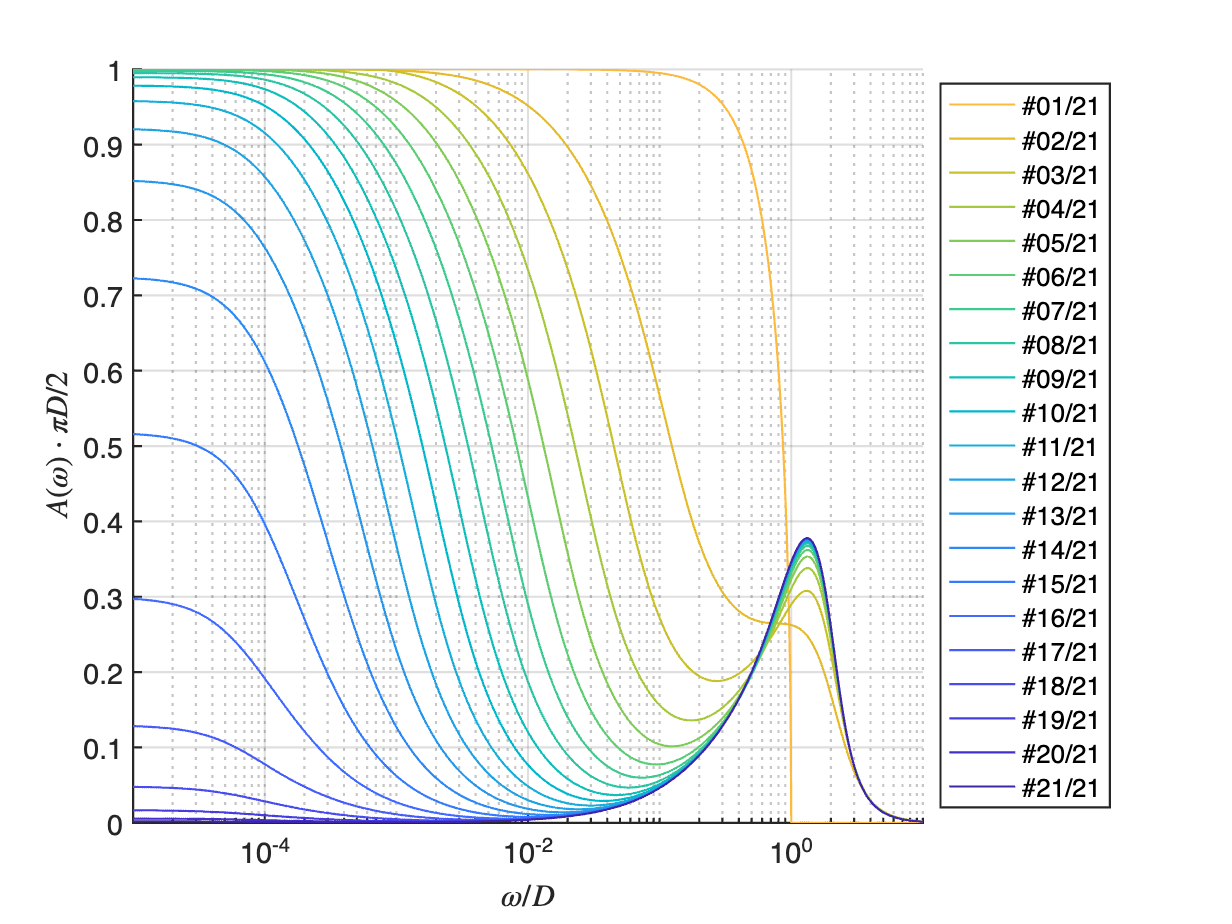

itU = 5;
cmap = parula(round(size(RhoV2_met{itU},2)*1.2));
cmap = flipud(cmap(1:size(RhoV2_met{itU},2),:)); % to avoid too bright colors
legs = cell(1,size(RhoV2_met{itU},2));

figure;
hold on;
for itd = (1:size(RhoV2_met{itU},2))
    plot(ocont/D,RhoV2_met{itU}(:,itd)/((D/2)^2)*(pi*D/2), ...
        'LineWidth',1,'Color',cmap(itd,:));
    legs{itd} = sprintf('#%02i/%02i',[itd size(RhoV2_met{itU},2)]);
end
hold off;

grid on;
set(gca,'LineWidth',1,'FontSize',13,'XScale','log');
legend(legs,'Location','eastoutside');
xlabel('$\omega / D$','Interpreter','latex');
ylabel('$A(\omega) \cdot \pi D/2$','Interpreter','latex');
xlim([0.1*T/D 10]);

The central peak narrows as the iteration goes, and once its width becomes comparable with $T = 10^{-4} D$, the peak height lowers. Then finally the peak disappears, opening the Mott gap.

## Solution to Exercise (c): Obtain the DMFT+NRG solutions starting from the $U = 3.5 D$ result

We continue from the script executed for Exercise (b) above. We take the converged hybridization function for $U = 3.5D$ as the initial hybridization function.

RhoV2init_ins = RhoV2_met{end}(:,end);

RhoV2_ins = cell(1,numel(Us));

for itU = (1:numel(Us))
    [~,RhoV2_ins{itU}] = DMFT_Hubbard(Us(itU),mus(itU),T,D, ...
        ocont,RhoV2init_ins,Lambda,N,Nkeep);
end

Here we use the suffix `_ins` in the variable names, since we start calculations from the insulating solution for $U = 3.5D$.

Plot the converged spectral functions. To compare with the results from Exercise (b), we plot them altogether.

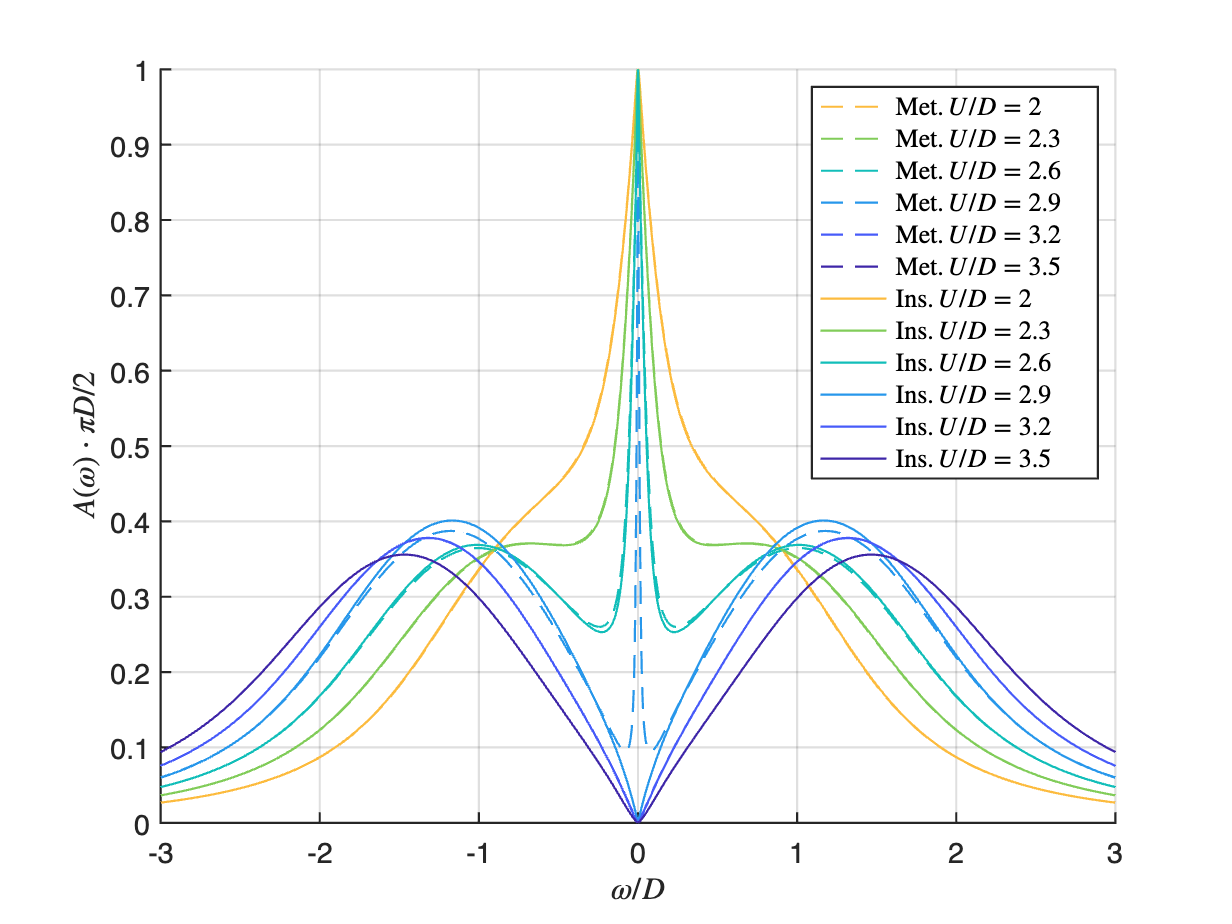

cmap = parula(round(numel(Us)*1.2));
cmap = flipud(cmap(1:numel(Us),:)); % to avoid too bright colors
legs = cell(numel(Us),2);

figure;
hold on;
for itU = (1:numel(Us))
    plot(ocont/D,RhoV2_met{itU}(:,end)/((D/2)^2)*(pi*D/2), ...
        'LineWidth',1,'LineStyle','--','Color',cmap(itU,:));
    legs{itU,1} = ['Met. $U/D = ',sprintf('%.4g',Us(itU)/D),'$'];
end
for itU = (1:numel(Us))
    plot(ocont/D,RhoV2_ins{itU}(:,end)/((D/2)^2)*(pi*D/2), ...
        'LineWidth',1,'LineStyle','-','Color',cmap(itU,:));
    legs{itU,2} = ['Ins. $U/D = ',sprintf('%.4g',Us(itU)/D),'$'];
end
hold off;

grid on;
set(gca,'LineWidth',1,'FontSize',13);
legend(legs(:).','Interpreter','latex');
xlabel('$\omega / D$','Interpreter','latex');
ylabel('$A(\omega) \cdot \pi D/2$','Interpreter','latex');
xlim([-1 1]*(3*D));

We find that the results for $U/D = 2.9$ differ depending on the choice of the initial hybridization. If the initial hybridization is metallic (insulating), the result is metallic (insulating). The presence of the two self-consistent solutions means that the system is in the co-existence regime for $U/D = 2.9$. In experiments, the co-existence can be confirmed by observing hysteresis.

According to the state-of-the-art DMFT+NRG calculation [[S.-S. B. Lee, J. von Delft, and A. Weichselbaum, Phys. Rev. Lett. **119**, 236402 (2017)](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.119.236402)], the system can be only metallic for $U < U_{c1} = 2.37(2)D$ and only insulating for $U > U_{c2} = 2.91(1)D$. Between $U_{c1}$ and $U_{c2}$, it is the co-existence regime.